## **Driver test program to check Clothoids library**

**Test clothoid**

Elapsed time is 24.449694 seconds.


Elapsed time is 16.246291 seconds.


Elapsed time is 48.647526 seconds.


Elapsed time is 23.310888 seconds.


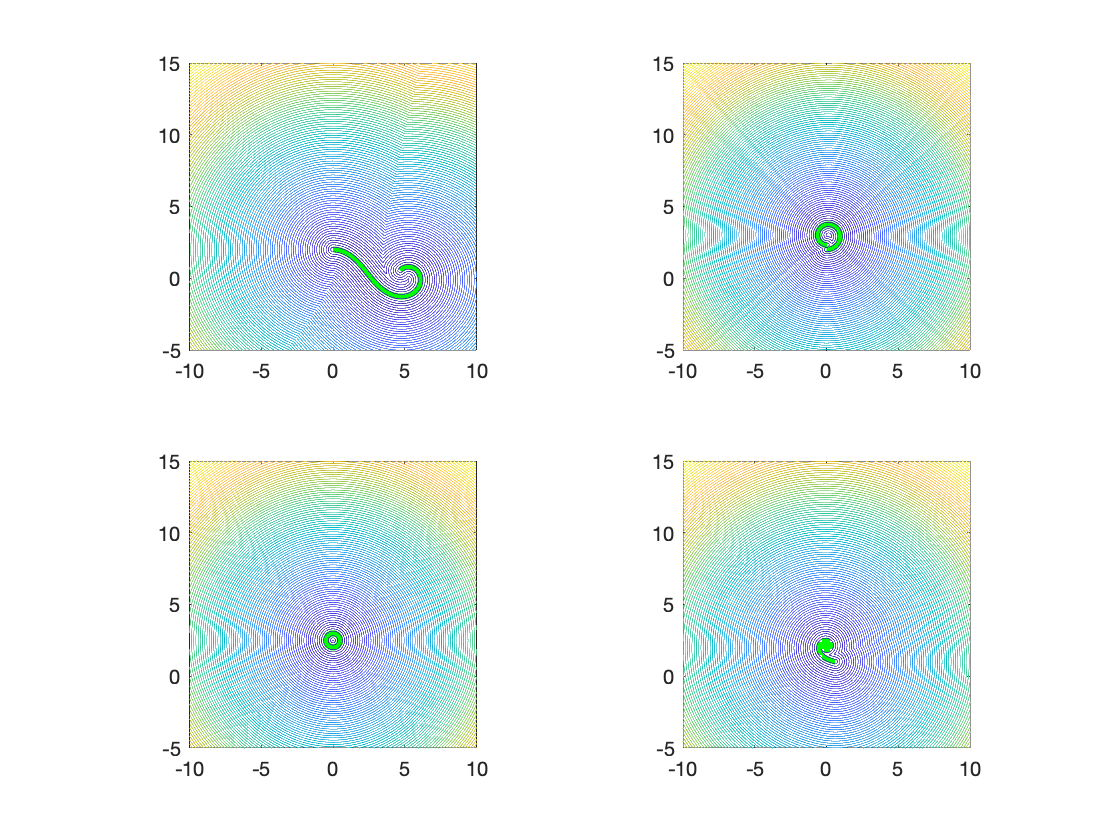

close all;

% check constructors
x0     = 0;
y0     = 2;
theta0 = 0;
kappa0 = [-0.6, 1, 2, 10];
dk     = [0.2, 0.1, 0.01, -1];
L      = [10,5,10,10];


for kk=1:4
  subplot(2,2,kk);
  L1 = ClothoidCurve( x0, y0, theta0, kappa0(kk), dk(kk), L(kk) );
  %
  L1.plot(1000,'Color','green','LineWidth',3);
  hold on;

  x     = -10:0.05:10;
  y     = -5:0.05:15;
  [X,Y] = meshgrid(x,y);

  tic
  ds = 0.01;
  Z  = L1.distanceBySample(X,Y,ds);
  toc

  contour(X,Y,Z,100)
  %surf(X,Y,Z)
  axis equal;
  %
  L1.delete();
end